data = readtable("HW3_data.xlsx");

test = data(1:50,:);

test = rows2vars(test,"VariableNamesSource","ID_REF")

test = 62×51 table
    OriginalVariableNames                     A_23_P100001                                 A_23_P100022                                A_23_P100056                                   A_23_P100074                              A_23_P100127                           A_23_P100141                A_23_P100189               A_23_P100196                              A_23_P100220                          A_23_P100240                 A_23_P10025                A_23_P100263                A_23_P100292                          A_23_P100315                                       A_23_P100326                                     A_23_P100341                                 A_23_P100355

X = cell2mat(test{3:end,2:end});
Y = data{end,4:end}';

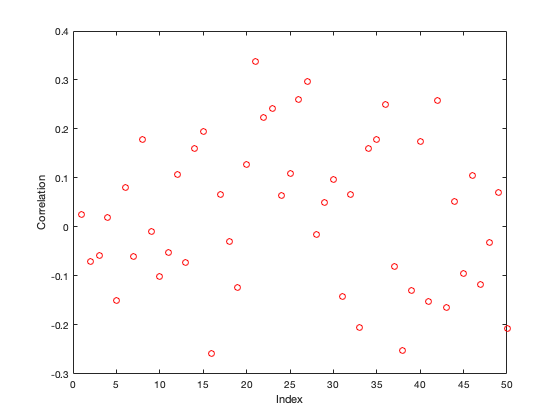

r = corr(X,Y);
plot(r,"ro")
xlabel("Index")
ylabel("Correlation")

find(abs(r>0.2))

ans =     21
    22
    23
    26
    27
    36
    42


X_new = X(:,find(abs(r>0.2)))

X_new =    -0.3024    0.0688   -0.1526   -0.3742    0.5430    0.0241    0.0505
    0.5793    1.4555    1.2965   -0.0222    0.7598    1.0287    0.1744
    0.0405   -0.8742    0.3139    0.8403    0.2531   -0.5873    0.6674
   -2.1395   -0.4983   -1.1117   -1.3763   -1.3044   -0.0360   -1.4992
   -0.0757   -0.2355    0.0076    0.1314   -0.2336    0.5591   -0.4370
    0.6812    0.3273   -0.0210    0.9245   -0.7920   -0.9781    0.1932
    0.5942    0.7368    0.1985    0.4548    1.2571    0.7953    1.0641
    0.0900   -0.2543   -0.2950   -0.5757   -0.2228    0.4158    0.1761
   -0.1393   -0.1142    0.0629   -0.0142    0.2403    0.1028   -0.9016
   -0.0972   -0.6539    0.0593    0.0696   -0.2306   -0.3826   -0.0308


mdl = fitlm(X_new,Y)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)     565.28     45.101      12.534    2.4479e-17
    x1              184.71     139.34      1.3257       0.19075
    x2              174.24     102.84      1.6944       0.09618
    x3             -211.97     121.19     -1.7491      0.086174
    x4              173.98     100.89      1.7245      0.090564
    x5              72.587     88.659     0.81873       0.41668
    x6              171.44      88.35      1.9405      0.057754
    x7             -80.815     117.21    -0.68946 

learner_table = [X,Y];

learner_table = 	1.0e+03 *

   -0.0008   -0.0019    0.0001    0.0003    0.0012    0.0000   -0.0001    0.0011   -0.0006   -0.0012    0.0001    0.0001    0.0002    0.0001   -0.0001   -0.0004    0.0010   -0.0003    0.0001    0.0002   -0.0003    0.0001   -0.0002    0.0001   -0.0007   -0.0004    0.0005   -0.0004   -0.0032    0.0003   -0.0005   -0.0007    0.0001    0.0002    0.0004    0.0000    0.0006    0.0003    0.0003    0.0005    0.0006    0.0001    0.0005   -0.0007   -0.0007    0.0002   -0.0013   -0.0004   -0.0001   -0.0010
   -0.0003   -0.0008   -0.0001    0.0003    0.0025    0.0000   -0.0001    0.0004    0.0003    0.0002   -0.0001    0.0010    0.0009    0.0007   -0.0002    0.0004    0.0008   -0.0001   -0.0001    0.0002    0.0006    0.0015    0.0013    0.0005   -0.0005   -0.0000    0.0008   -0.0000   -0.0003    0.0020   -0.0019    0.0002   -0.0019    0.0002   -0.0005    0.0010   -0.0021   -0.0002    0.0000    0.0004   -0.0004    0.0002    0.0006    0.0000    0.0003   -0.0003    0.0003 